# DTMF Decoding of recorded radio traffic

Jason Hillebrand - HLLJAS007

Torsten Babl - BBLTOR001

## DTMF Frequencies

Cols: 1209, 1336, 1477,1633

Rows: 697, 770, 852, 941 Hz

input_filenames = {'audio\all_keysx3.wav', 'audio\1-10.wav', 'audio\phone_number.wav'};

[rec, Fs] = audioread(input_filenames{1});
rec = rec(1:end,1); % Stereo to mono

dtmf_freqs = [697, 770, 852, 941, 1209, 1336, 1477, 1633];
load("667Filter.mat")
load("770Filter.mat")
load("852Filter.mat")
load("941Filter.mat")
load("1209Filter.mat")
load("1336Filter.mat")
load("1477Filter.mat")
load("1633Filter.mat")
load("lpfFilter.mat")




Row1 = downsample(filter(Hd,rec),5);
Row2 = downsample(filter(Hd2,rec),5);
Row3 = downsample(filter(Hd3,rec),5);
Row4 = downsample(filter(Hd4,rec),5);
Collum1 = downsample(filter(Hd5,rec),5);
Collum2 = downsample(filter(Hd6,rec),5);
Collum3 = downsample(filter(Hd7,rec),5);
Collum4 = downsample(filter(Hd8,rec),5);
figure
plot(rec)
title('Sampled data from SDR sampled at 50k samples/second')
xlabel('Samples')

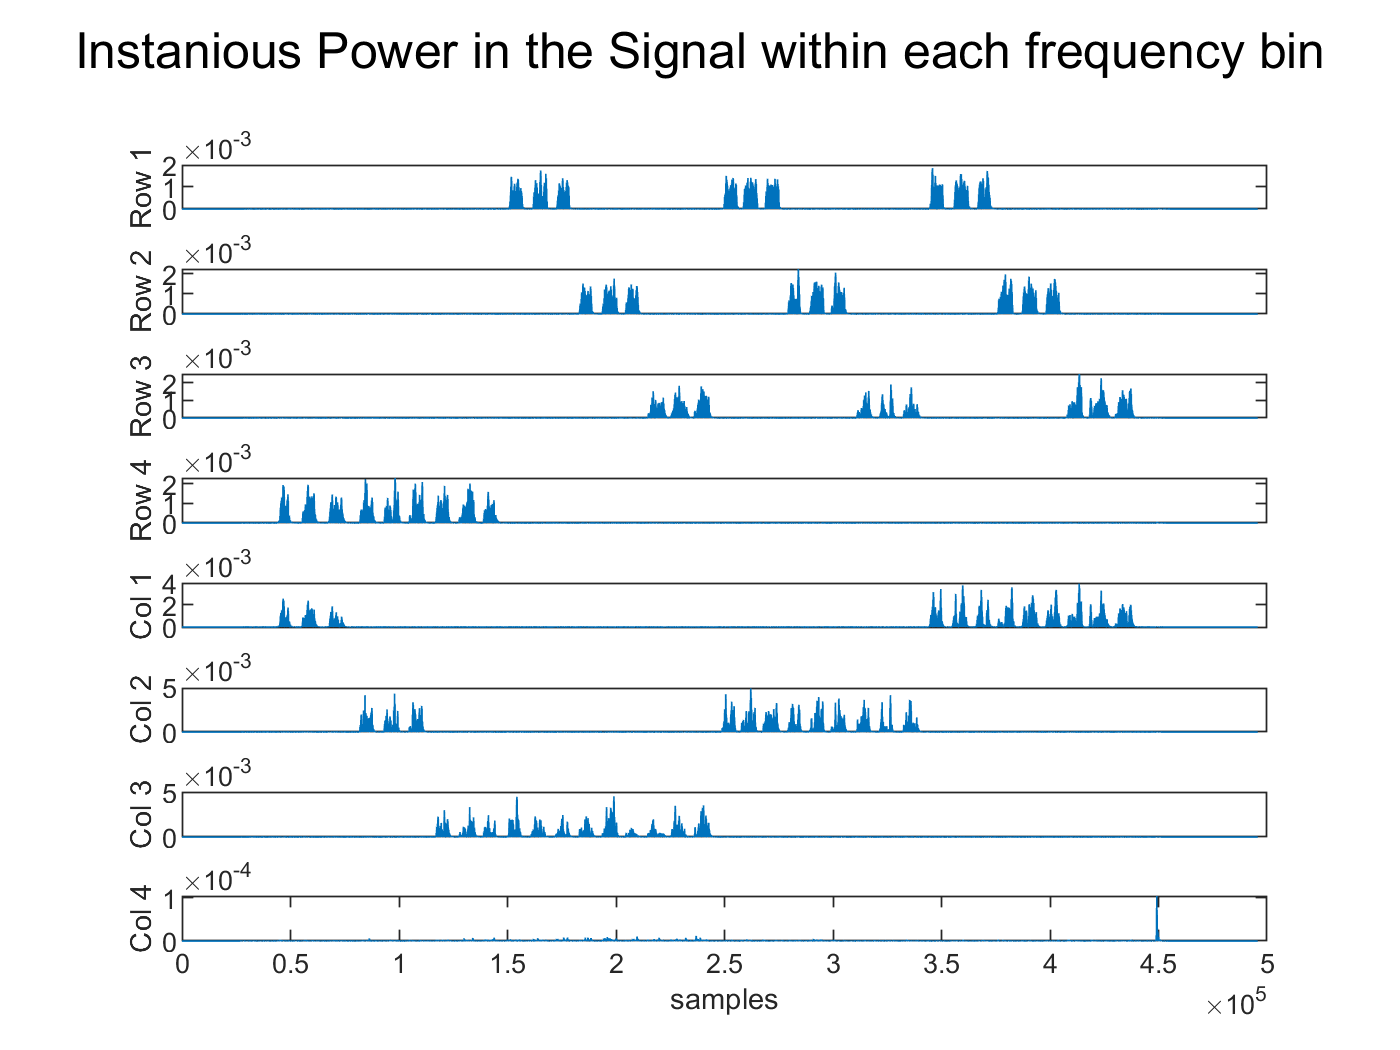

figure

subplot(8,1,1)
plot(Row1.^2)
ylabel('Row 1')
set(gca,'XTick',[])


subplot(8,1,2)
plot(Row2.^2)
ylabel('Row 2')
set(gca,'XTick',[])

subplot(8,1,3)
plot(Row3.^2)
ylabel('Row 3')
set(gca,'XTick',[])

subplot(8,1,4)
plot(Row4.^2)
ylabel('Row 4')
set(gca,'XTick',[])

subplot(8,1,5)
plot((Collum1).^2)
ylabel('Col 1')
set(gca,'XTick',[])

subplot(8,1,6)
plot(Collum2.^2)
ylabel('Col 2')
set(gca,'XTick',[])

subplot(8,1,7)
plot(Collum3.^2)
ylabel('Col 3')
set(gca,'XTick',[])

subplot(8,1,8)
plot(Collum4.^2)
ylabel('Col 4')
xlabel('samples')
sgtitle('Instanious Power in the Signal within each frequency bin')


BoolRow1 = booleanSmoother(downsample(Row1.^2 > max(Row1.^2)*0.05,10^2));
BoolRow2 = booleanSmoother(downsample(Row2.^2 > max(Row2.^2)*0.01,10^2));
BoolRow3 = booleanSmoother(downsample(Row3.^2 > max(Row3.^2)*0.01,10^2));
BoolRow4 = booleanSmoother(downsample(Row4.^2 > max(Row4.^2)*0.01,10^2));
BoolCollum1 = booleanSmoother(downsample(Collum1.^2 >max(Row1.^2)*0.01,10^2));
BoolCollum2 = booleanSmoother(downsample(Collum2.^2 >max(Collum1.^2)*0.01,10^2));
BoolCollum3 = booleanSmoother(downsample(Collum3.^2 >max(Collum1.^2)*0.01, 10^2));
BoolCollum4 = booleanSmoother(downsample( Collum4.^2 >max(Collum3.^2)*0.01,10^2));

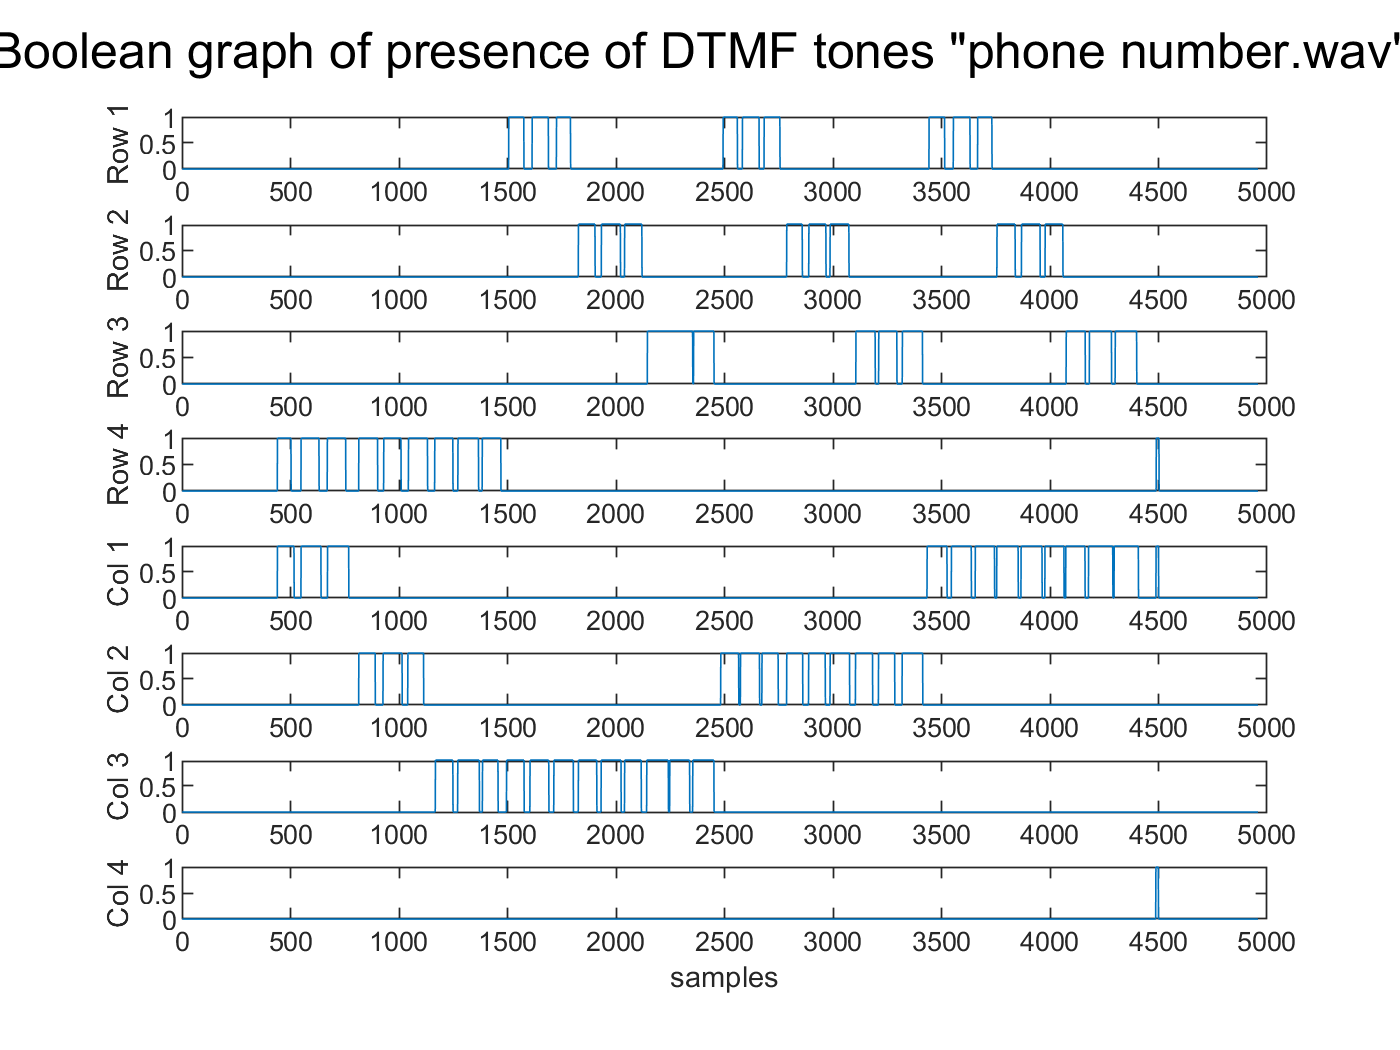

figure
subplot(8,1,1)
plot(BoolRow1)
ylabel('Row 1')


subplot(8,1,2)
plot(BoolRow2)
ylabel('Row 2')

subplot(8,1,3)
plot(BoolRow3)
ylabel('Row 3')

subplot(8,1,4)
plot(BoolRow4)
ylabel('Row 4')

subplot(8,1,5)
plot(BoolCollum1)
ylabel('Col 1')

subplot(8,1,6)
plot(BoolCollum2)
ylabel('Col 2')

subplot(8,1,7)
plot(BoolCollum3)
ylabel('Col 3')

subplot(8,1,8)
plot(BoolCollum4)
ylabel('Col 4')
xlabel('samples')
sgtitle('Boolean graph of presence of DTMF tones "phone number.wav"')

output = Bool2Symbol(BoolRow1,BoolRow2,BoolRow3,BoolRow4,BoolCollum1,BoolCollum2,BoolCollum3,BoolCollum4).';
output.'

ans = 1×74 string array
    "*"    "."    "*"    "."    "*"    "."    "0"    "."    "0"    "."    "0"    "."    "#"    "."    "#"    "."    "#"    "."    "3"    "."    "3"    "."    "3"    "."    "6"    "."    "6"    "."    "6"    "."    "9"    "."    "9"    "."    "9"    "."    "2"    "."    "2"    "."    "2"    "."    "5"    "."    "5"    "."    "5"    "."    "8"    "."    "8"    "."    "8"    "."    "1"    "."    "1"    "."    "1"    "."    "4"    "."    "4"    "."    "4"    "."    "7"    "."    "7"    "."    "7"    "."    "*"    "."
